% load data 
wdbc_data_orig = readtable("wdbc.data.txt");
[nrows, ncols] = size(wdbc_data_orig)

nrows = 569

ncols = 32


wdbc_data = wdbc_data_orig(:, 3:ncols);
wdbc_data = table2array(wdbc_data)

wdbc_data = 	1.0e+03 *

    0.0180    0.0104    0.1228    1.0010    0.0001    0.0003    0.0003    0.0001    0.0002    0.0001    0.0011    0.0009    0.0086    0.1534    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0254    0.0173    0.1846    2.0190    0.0002    0.0007    0.0007    0.0003    0.0005    0.0001
    0.0206    0.0178    0.1329    1.3260    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0005    0.0007    0.0034    0.0741    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0250    0.0234    0.1588    1.9560    0.0001    0.0002    0.0002    0.0002    0.0003    0.0001
    0.0197    0.0213    0.1300    1.2030    0.0001    0.0002    0.0002    0.0001    0.0002    0.0001    0.0007    0.0008    0.0046    0.0940    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0236    0.0255    0.1525    1.7090    0.0001    0.0004    0.0005    0.0002    0.0004    0.0001
    0.0114    0.0204    0.0776    0.3861    0.0001    0.0003    0.0002   

wdbc_group = wdbc_data_orig.Var2;

M = wdbc_data(wdbc_group(1:500) == "M", :); % Malicious
B = wdbc_data(wdbc_group(1:500) == "B", :); % Benign

[mcnt, num_features] = size(M);
[bcnt, ~           ] = size(B);

% quadraic programming
tau = 1000;
quadratic = diag([ones(num_features, 1); zeros(1 + mcnt + bcnt, 1)]);
linear = [zeros(num_features + 1, 1); tau * ones(mcnt + bcnt, 1)];
% malicious
malicious_lhs = [-M ones(mcnt, 1) -eye(mcnt) zeros(mcnt, bcnt)];
benigh_lhs = [B -ones(bcnt, 1) zeros(bcnt, mcnt) -eye(bcnt)];
mb_rhs = -ones(mcnt + bcnt, 1);

% solve
[xstar, fstar] = quadprog(quadratic, linear, ...
                          [malicious_lhs;benigh_lhs], mb_rhs, ...
                          [], [], ...
                          [-inf*ones(num_features + 1, 1); ...
                            zeros(mcnt + bcnt, 1)] ...
                         ); 


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


fstar

fstar = 1.9427e+04

alpha = xstar(1:30)

alpha =    -7.0337
   -0.0094
    0.6434
    0.0328
    2.4662
  -14.3500
   -6.4099
   11.4022
    7.6009
    2.3617


bias = xstar(31)

bias = 25.8190


plane = @(x) x * alpha - bias

plane = function_handle with value:
    @(x)x*alpha-bias


sum(plane(M) >= 1) / mcnt, sum(plane(B) <= -1) / bcnt

ans = 0.9436

ans = 0.9672

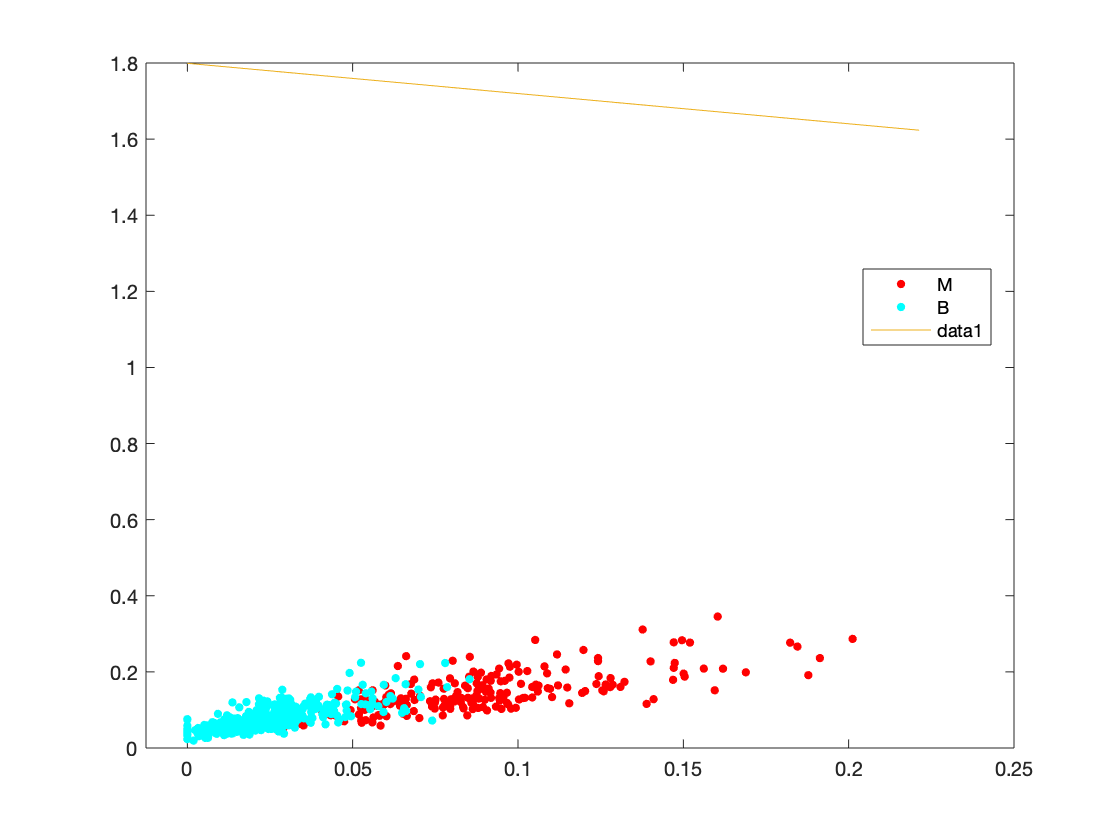

xidx = 8;
yidx = 6;

gscatter(wdbc_data(:, xidx), wdbc_data(:, yidx), wdbc_group);
hold on

px = linspace(0.9 * min(wdbc_data(:, xidx)), ...
              1.1 * max(wdbc_data(:, xidx)));
py = (alpha(xidx) * px - bias) / alpha(yidx);

plot(px, py)

hold off

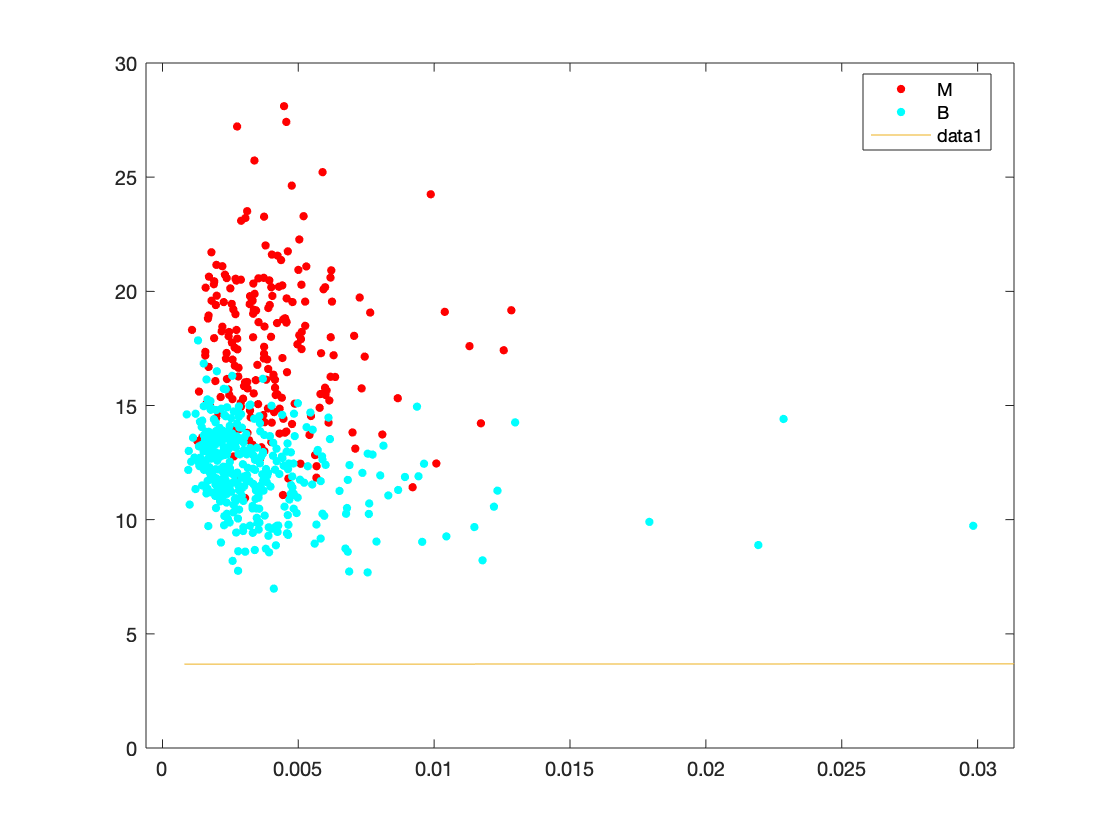

xidx = 20;
yidx = 1;

gscatter(wdbc_data(:, xidx), wdbc_data(:, yidx), wdbc_group);
hold on

px = linspace(0.9 * min(wdbc_data(:, xidx)), ...
              1.1 * max(wdbc_data(:, xidx)));
py = (alpha(xidx) * px - bias) / alpha(yidx);

plot(px, py)

hold off

% determine whether the data is indeed separable

u = xstar(32:31+mcnt)

u =     0.3115
    0.3116
    0.3117
    0.3117
    0.3116
    0.3120
    0.3117
    0.3118
    0.3117
    0.3117


v = xstar(31+mcnt+1:31+mcnt+bcnt)

v =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.6769
    0.0000
    0.0000
    0.0000



sum(abs(u) <= eps(max(u))), sum(abs(v) <= eps(max(v)))

ans = 189

ans = 299


slack = [u;v]; eps(max(slack))

ans = 8.8818e-16

sum(abs(slack) <= eps(max(slack)))

ans = 488

% test SVM with the remaining part of the data
wdbc_test = wdbc_data(501:nrows, :); 
wdbc_test_group = wdbc_group(501:nrows, :);
M_test = wdbc_test(wdbc_test_group == "M", :);
B_test = wdbc_test(wdbc_test_group == "B", :);

[mtestcnt, ~] = size(M_test)

mtestcnt = 17

[btestcnt, ~] = size(B_test)

btestcnt = 52


sum(plane(M_test) >= 1) / mtestcnt

ans = 1

sum(plane(B_test) <= -1) / btestcnt

ans = 0.9423

sum(plane(M_test) <= -1) / mtestcnt

ans = 0

sum(plane(B_test) >= 1) / btestcnt

ans = 0.0192

sum(plane(M_test) < 1 & plane(M_test) > -1) / mtestcnt

ans = 0

sum(plane(B_test) < 1 & plane(B_test) > -1) / btestcnt

ans = 0.0385